## Load Data

clear
clc

% Path To Data
VONNPath = pwd; % VONN LAB Dropbox
CS670Path = fullfile(VONNPath,"Patrick Do/CS670/" );

dataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Train_25PerClass";
dataFolder = fullfile(CS670Path, "Data_CS670", dataOpt);

% Load Train Data
imdsTrain = imageDatastore(dataFolder, ...
        "IncludeSubfolders",true, "LabelSource", "foldernames", ...
        "FileExtensions", ".mat", "ReadFcn",@loadPD);


% Load Test Data
valDataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Test_175PerClass";
valDataFolder = fullfile(CS670Path, "Data_CS670", valDataOpt);
imdsVal = imageDatastore(valDataFolder, ...
        "IncludeSubfolders",true, "LabelSource", "foldernames", ...
        "FileExtensions", ".mat", "ReadFcn",@loadPD);

## Extract Features

% Load ATLAS
load(fullfile(VONNPath, 'CollaboratingProjects/AVOProject/Report/March25_26_All','imMask.mat'));
numROI = 95;

% Train set
numTrain = length(imdsTrain.Labels);
ROITrain = zeros(numTrain, numROI);
parfor k=1:numTrain
    im = readimage(imdsTrain, k);
    for ROI_thr = 1:numROI
        ROI_ind = find(imMask == ROI_thr);
        ROITrain(k, ROI_thr) = mean(im(ROI_ind));
    end
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


YTrain = imdsTrain.Labels;

% Validation set
numTest = length(imdsVal.Labels);
ROITest = zeros(numTest, numROI);
parfor k=1:numTest
    im = readimage(imdsVal, k);
    for  ROI_thr = 1:numROI
        ROI_ind = find(imMask == ROI_thr);
        ROITest(k, ROI_thr) = mean(im(ROI_ind));
    end
end
YTest = imdsVal.Labels;

classes = unique(imdsTrain.Labels);
% model = fitcsvm(...
%     ROITrain, ...
%     YTrain, ...
%     'KernelFunction', 'polynomial', ...
%     'PolynomialOrder', 3, ...
%     'KernelScale', 'auto', ...
%     'BoxConstraint', 1, ...
%     'Standardize', true, ...
%     'ClassNames', classes);

model =  fitcsvm(...
    ROITrain, ...
    YTrain, ...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 9.699999999999999, ...
    'BoxConstraint', 1, ...
    'Standardize', true, ...
    'ClassNames', classes);

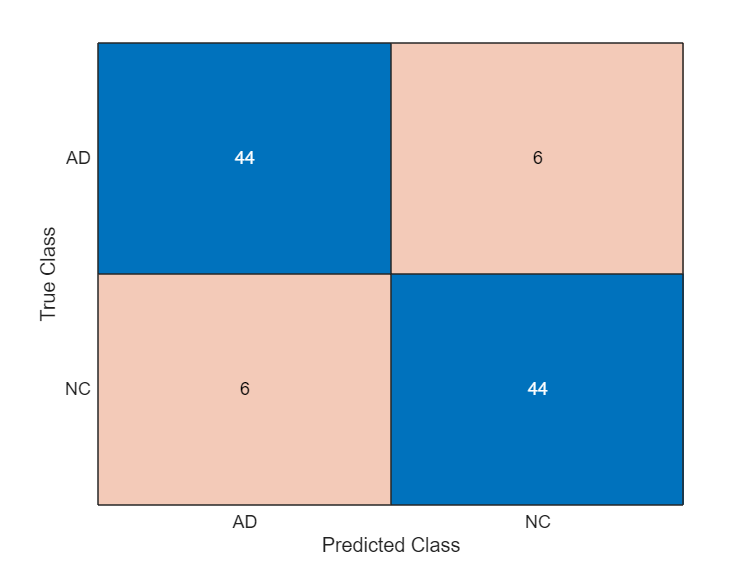

cmTrain =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


YPredTrain = predict(model, ROITrain);
cmTrain = confusionchart(YTrain, YPredTrain)

resTrain = performanceMetrics(cmTrain.NormalizedValues)

resTrain = struct with fields:
       accuracy: 0.8800
    sensitivity: 0.8800
    specificity: 0.8800
      precision: 0.8800
            FDR: 0.1200
       f1_score: 0.8800


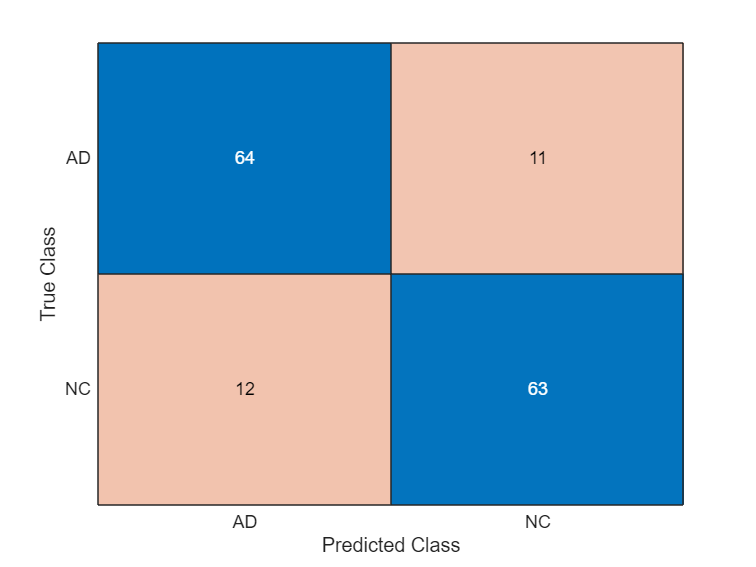

cmTest =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


YPredTest = predict(model, ROITest);
cmTest = confusionchart(YTest, YPredTest)

resTest = performanceMetrics(cmTest.NormalizedValues)

resTest = struct with fields:
       accuracy: 0.8467
    sensitivity: 0.8533
    specificity: 0.8400
      precision: 0.8421
            FDR: 0.1579
       f1_score: 0.8477


% SHAP_scores = calculateSHAP(quadraticSVM, ROITrain);

LIME_scores_train = calculateLIME(model, ROITrain, 95);
LIME_scores_test = calculateLIME(model, ROITest, 95);

modelName = "gaussianSVM";

augmentedImageFolder = fullfile(CS670Path, "Augmented_Data_V1_CS670", dataOpt);
if ~exist(augmentedImageFolder, "dir")
    mkdir(augmentedImageFolder);
end
save(fullfile(augmentedImageFolder, "importanceScore.mat"), ...
    "LIME_scores_train", "LIME_scores_test", "model", "modelName")

## Functions

function feature_importance = calculateSHAP(model, X)
    % Inputs:
    % - model: Trained model
    % - X: Data matrix of size (numSubjects x numFeatures)

    % Initialize variables
    numSubjects = size(X, 1);
    numFeatures = size(X, 2);
    feature_importance = zeros(numSubjects, numFeatures);
    
    % Compute the contribution of each feature for each subject using SHAP approximation
    for i = 1:numSubjects
        x_instance = X(i, :); % Get the i-th subject data
        
        % Calculate SHAP values of the current subject
        explainer = shapley(model, QueryPoints=x_instance, UseParallel=true);
        feature_importance(i,:) = explainer.Shapley.AD;
    end
end

function feature_importance = calculateLIME(model, X, numImportantFeatures)
    % Inputs:
    % - model: Trained model
    % - X: Data matrix of size (numSubjects x numFeatures)

    % Initialize variables
    numSubjects = size(X, 1);
    numFeatures = size(X, 2);
    feature_importance = zeros(numSubjects, numFeatures);
    
    % Compute the contribution of each feature for each subject using SHAP approximation
    parfor i = 1:numSubjects
        x_instance = X(i, :); % Get the i-th subject data
        
        % Calculate LIME values of the current subject
        explainer = lime(model, "QueryPoint", x_instance, "NumImportantPredictors", numImportantFeatures);
        feature_importance(i,:) = explainer.SimpleModel.Beta;
    end
end
